# ES 155 Control Example: Speed Control of Autonomous Driving

## Control Goals:

- Stability/Performance: 1) Steady state velocity approaches desired velocity $v_d$; 2)  Smooth response; no overshoot or oscillations

- Disturbance rejection: 1) Effect of disturbances (eg, hills) approaches zero

- Robustness: 2) Results don’t depend on the specific values of the system parameters

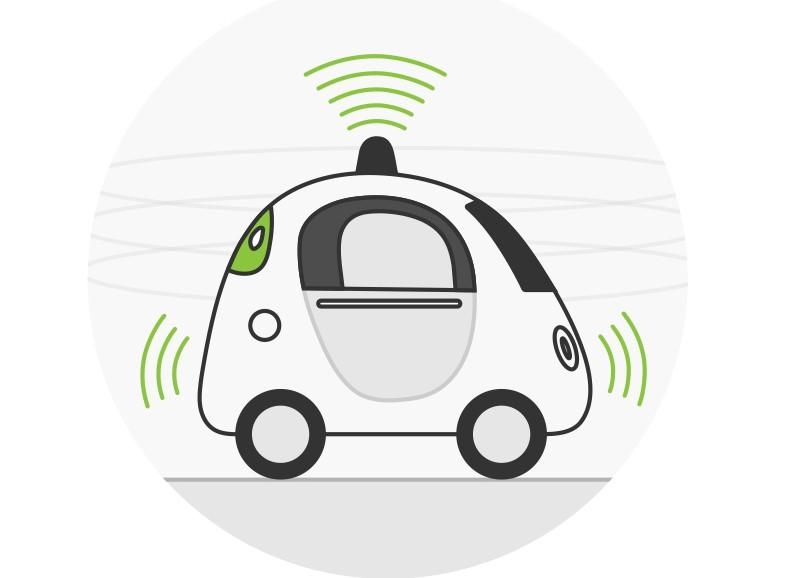

## System Modelling 

- System variable: Speed $\left(v\right)$ and postion $\left(y\right)$

- System parameter: mass $\left(m\right)$

- Disturbance: Force $\left(F_{\mathrm{hill}} \right)$

- Viscocity: $-\delta \times v$

- Actuator: Engine/Braking Force $F_{\mathrm{engine}}$

## System Model


$$m\dot{v} =-\delta \times v+F_{\mathrm{engine}} +F_{\mathrm{hill}}$$


or we can include the vehicle's position explicilty 


$$\left\lbrack \begin{array}{c}
\dot{\;y} \\
\dot{\;v} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
v\\
\frac{1}{m}\left(-\delta \times v+F_{\mathrm{engine}} +F_{\mathrm{hill}} \right)
\end{array}\right\rbrack \ldotp$$


## Control design: Design $F_{\textrm{engine}}$ to reach the desried speed $v_d$

clear all;
%% System paramters
m     = 10;      % mass
delta = 0;       % Viscocity coefficient, for simplicity, 
                 % assumed to be zero for Case 1 & Case 2;
Fhill = 0;       % Assume the vehicle runs on a flat road; 

V0    = 0;       % initial velocity m/s
Vdes  = 1;     % Desired velocity m/s

% put all system parameter into one single variable
para.m     = m; 
para.delta = delta; 
para.Fhill = Fhill;
para.V0    = V0;
para.Vdes  = Vdes;


tspan = [0,30]; % simulation time period
y0    = [0;V0]; % initial conditon



## Case 1: Apply no control

    Here, we simply apply the following strategy

    
$$F_{\textrm{engine}} =0,\forall \;t\ge 0$$


    In this case, the vehicle will maitain a constant velocity, sicne we assume $F_{\textrm{hill}} =0$ and $\delta =0$

    You can change the value of $\delta$, and see the output. Can you explain the result?

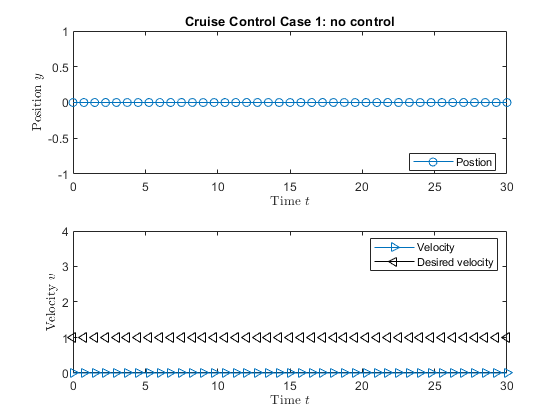


%% simulate the vehicle's trajectory when no input is applied
[t,y] = ode45(@(t,y) VehicleNocontrol(t,y,para),tspan,y0);

% plot
figure
subplot(2,1,1);
plot(t,y(:,1),'-o')
title('Cruise Control Case 1: no control');
xlabel('Time $t$','Interpreter','latex');
ylabel('Position $y$','Interpreter','latex');
legend('Postion','Location','best');

subplot(2,1,2);
plot(t,y(:,2),'->'); hold on;
plot(t,Vdes,'k-<');
ylim([0,4])

xlabel('Time $t$','Interpreter','latex');
ylabel('Velocity $v$','Interpreter','latex');
legend('Velocity','Desired velocity','Location','best');

## Case 2: Open-loop/Feedforward control

Here, we apply the following open-loop strategy

    
$$F_{\textrm{engine}} =\left\lbrace \begin{array}{cc}
2 & t\le 10\\
0 & \mathrm{otherwise}
\end{array}\right.\;$$


    In this case, the vehicle will accelerate for 10 seconds, and then maintain a constant velocity;

    Can we achieve the destired velocity $v_d$?

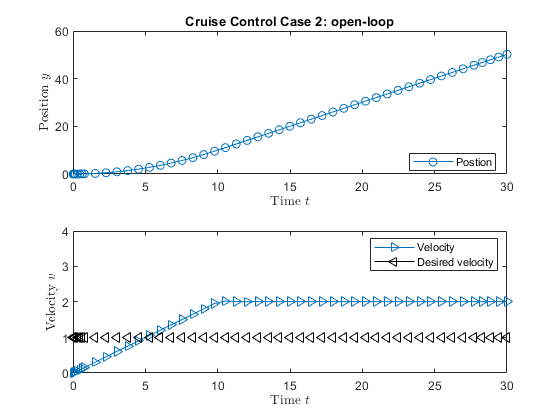


%% simulate the vehicle's trajectory when an open-loop is applied
y0    = [0;V0];
[t,y] = ode45(@(t,y) VehicleOpenloop(t,y,para),tspan,y0);

% plot
figure
subplot(2,1,1);
plot(t,y(:,1),'-o')
title('Cruise Control Case 2: open-loop');
xlabel('Time $t$','Interpreter','latex');
ylabel('Position $y$','Interpreter','latex');
legend('Postion','Location','best');

subplot(2,1,2);
plot(t,y(:,2),'->');hold on;
plot(t,Vdes,'k-<');
ylim([0,4])

xlabel('Time $t$','Interpreter','latex');
ylabel('Velocity $v$','Interpreter','latex');
legend('Velocity','Desired velocity','Location','best');

## Case 3: Feedback control with a propotional term

Here, we apply the following feedback strategy

    
$$F_{\textrm{engine}} =-k_p \left(v-v_{\mathrm{des}} \right)$$


    where $k_p$ is the proptional gain (chosed to be positive). 

    Can we achieve the destired velocity $v_d$? Observe we always have a steady-state error;

    Can we always achieve a stable velocity? You can play with the paramemter $k_p$ to see some numerical results. 

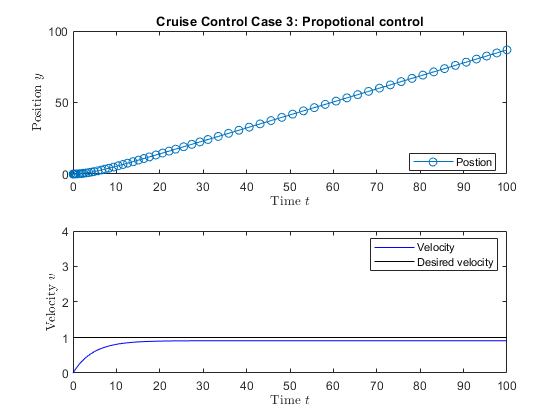

%% simulate the vehicle's trajectory when a P-control is applied

para.delta = 0.2;
Kp      = 2;          % try 4 6 8 10
para.Kp = Kp;

tspan = [0,100];
y0    = [0;V0];
[t,y] = ode45(@(t,y) VehicleP(t,y,para),tspan,y0);


% plot
figure
subplot(2,1,1);
plot(t,y(:,1),'-o')
title('Cruise Control Case 3: Propotional control');
xlabel('Time $t$','Interpreter','latex');
ylabel('Position $y$','Interpreter','latex');
legend('Postion','Location','best');

subplot(2,1,2);
plot(t,y(:,2),'b-');hold on;
plot(t,Vdes*ones(length(t),1),'k-');
ylim([0,4])

xlabel('Time $t$','Interpreter','latex');
ylabel('Velocity $v$','Interpreter','latex');
legend('Velocity','Desired velocity','Location','best');


fprintf('steady state error: %4.2f m/s \n',Vdes - y(end,2));

steady state error: 0.09 m/s 


## Case 4: Feedback control with a propotional+integral term

Here, we apply the following feedback strategy

    
$$F_{\textrm{engine}} =-k_p \left(v-v_{\textrm{des}} \right)-k_i \int_0^t \left(v-v_{\textrm{des}} \right)\textrm{dt}$$


where $k_p$ is the proptional gain (chosed to be positive). 

For simulation, we introduce a new variable, $q=\int_0^t \left(v-v_{\textrm{des}} \right)\textrm{dt}$, then 


$$\begin{array}{l}
\dot{\;y} =v\\
\dot{\;q} =v_{\textrm{des}} -v,\\
\dot{\;v} =\frac{1}{m}\left(-\delta \times v+F_{\textrm{engine}} +F_{\textrm{hill}} \right)\\
F_{\textrm{engine}} ={-k}_p \left(v-v_{\textrm{des}} \right)-k_i q
\end{array}$$


    Can we achieve the destired velocity $v_d$?

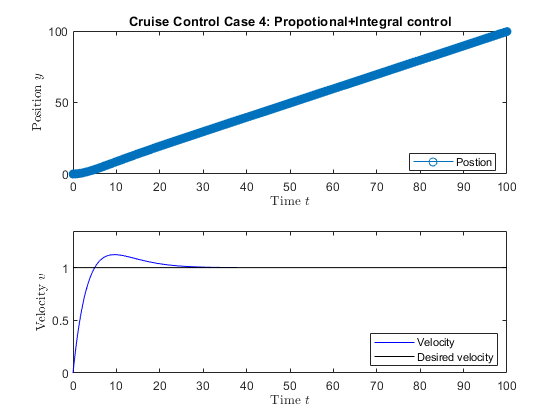

%% simulate the vehicle's trajectory when a PI-control is applied

para.delta = 0.2;
tspan = 0:0.1:100;
Kp = 4;         
Ki = 0.5;
para.Kp = Kp;
para.Ki = Ki;

y0 = [0;V0;0];  % augmented to give the initial state for q.


[t,y] = ode45(@(t,y) VehiclePI(t,y,para),tspan,y0);

% plot
figure
subplot(2,1,1);
plot(t,y(:,1),'-o')
title('Cruise Control Case 4: Propotional+Integral control');
xlabel('Time $t$','Interpreter','latex');
ylabel('Position $y$','Interpreter','latex');
legend('Postion','Location','best');

subplot(2,1,2);
plot(t,y(:,2),'b-');hold on;
plot(t,Vdes*ones(length(t),1),'k-');
ylim([0,max(y(:,2))*1.2])

xlabel('Time $t$','Interpreter','latex');
ylabel('Velocity $v$','Interpreter','latex');
legend('Velocity','Desired velocity','Location','best');


fprintf('steady state error: %4.2f m/s \n',Vdes - y(end,2));

steady state error: -0.00 m/s 


## Control strategies

function ydot = VehicleNocontrol(t,y,para)
% Vehicle dynamcis with no control input
% t: time;   y: position and velocity;  para: system parameters

    m     = para.m;           % mass
    delta = para.delta;       % Viscocity coefficient
    Fhill = para.Fhill;       % 
      
    % No control input
    Fengine = 0;
    
    ydot = zeros(2,1);
    % dynamcis
    ydot(1) = y(2);                              % position part
    ydot(2) = (-delta*y(2) + Fhill + Fengine)/m; % velocity part
    
end

function ydot = VehicleOpenloop(t,y,para)
% Vehicle dynamcis with open-loop control
% t: time;   y: position and velocity;  para: system parameters

    m     = para.m;           % mass
    delta = para.delta;       % Viscocity coefficient
    Fhill = para.Fhill;       % 
      
    % Open-loop control
    if t <= 10
        Fengine = 2;
    else
        Fengine = 0;
    end
    
    ydot = zeros(2,1);
    % dynamcis
    ydot(1) = y(2);                              % position part
    ydot(2) = (-delta*y(2) + Fhill + Fengine)/m; % velocity part
    
end

%%
function ydot = VehicleP(t,y,para)
% Vehicle dynamcis with propotional control
% t: time;   y: position and velocity;  para: system parameters

    m     = para.m;           % mass
    delta = para.delta;       % Viscocity coefficient
    Fhill = para.Fhill;       % 
    
    Vdes  = para.Vdes;
    Kp    = para.Kp;
      
    % Propotional control
    Fengine = Kp * (Vdes - y(2));
    
    ydot = zeros(2,1);
    % dynamcis
    ydot(1) = y(2);                              % position part
    ydot(2) = (-delta*y(2) + Fhill + Fengine)/m; % velocity part
    
end

%%
function ydot = VehiclePI(t,y,para)
% Vehicle dynamcis with propotional control
% t: time;   y: position, velocity, and a new variable q;  para: system parameters

    m     = para.m;           % mass
    delta = para.delta;       % Viscocity coefficient
    Fhill = para.Fhill;       % 
    
    Vdes = para.Vdes;
    Kp   = para.Kp;
    Ki   = para.Ki;
      
    % Propotional + Integral control
    Fengine = -Kp * (y(2)-Vdes) - Ki*y(3);
    
    ydot = zeros(2,1);
    % dynamcis
    ydot(1) = y(2);                              % position part
    ydot(2) = (-delta*y(2) + Fhill + Fengine)/m; % velocity part
    ydot(3) = y(2) - Vdes;                       % new variable for integration
end
